Class 1: iTAML\cifar10\iTAML_ses_0_XA_dcts.mat


Class 2: iTAML\cifar10\iTAML_ses_4_XA_dcts.mat



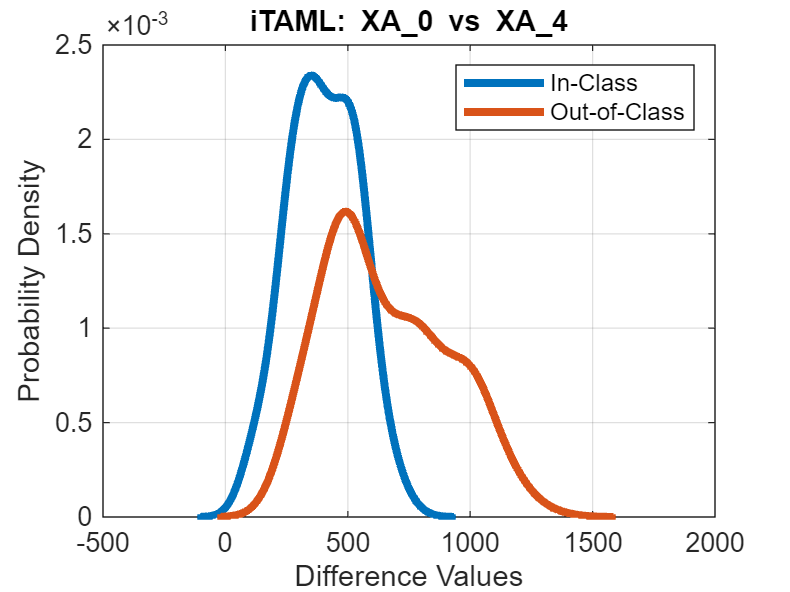

Class 1: RPSnet\cifar10\RPSnet_ses_0_XA_dcts.mat


Class 2: RPSnet\cifar10\RPSnet_ses_4_XA_dcts.mat



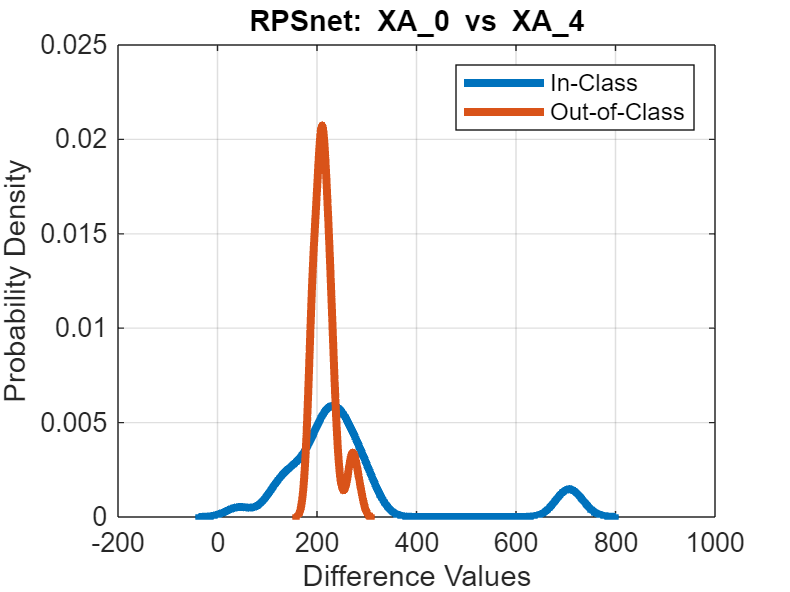

Class 1: foster\cifar10\foster_ses_0_XA_dcts.mat


Class 2: foster\cifar10\foster_ses_4_XA_dcts.mat



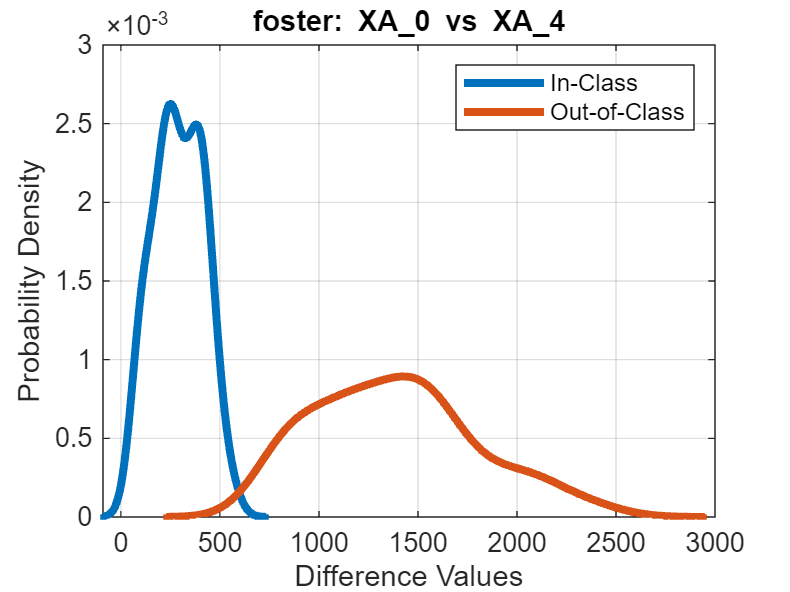

Class 1: memo\cifar10\memo_ses_0_XA_dcts.mat


Class 2: memo\cifar10\memo_ses_4_XA_dcts.mat



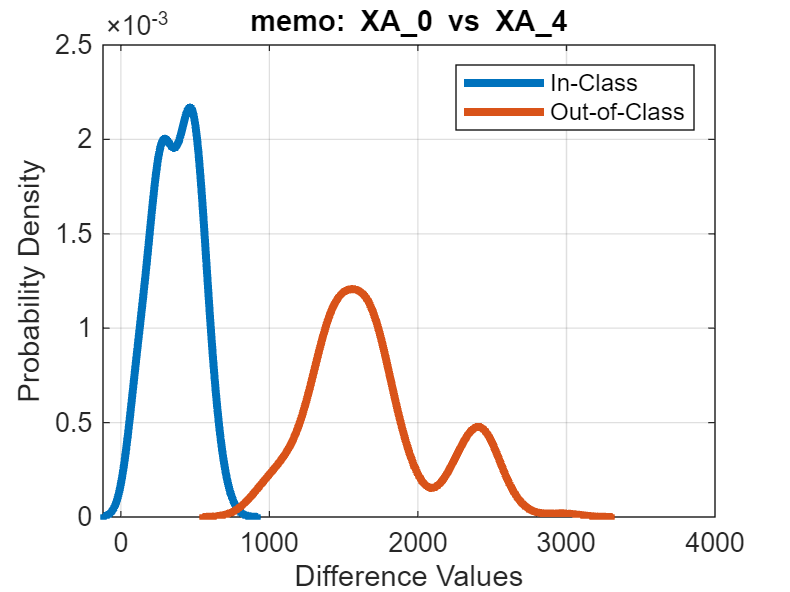

Class 1: der\cifar10\der_ses_0_XA_dcts.mat


Class 2: der\cifar10\der_ses_4_XA_dcts.mat



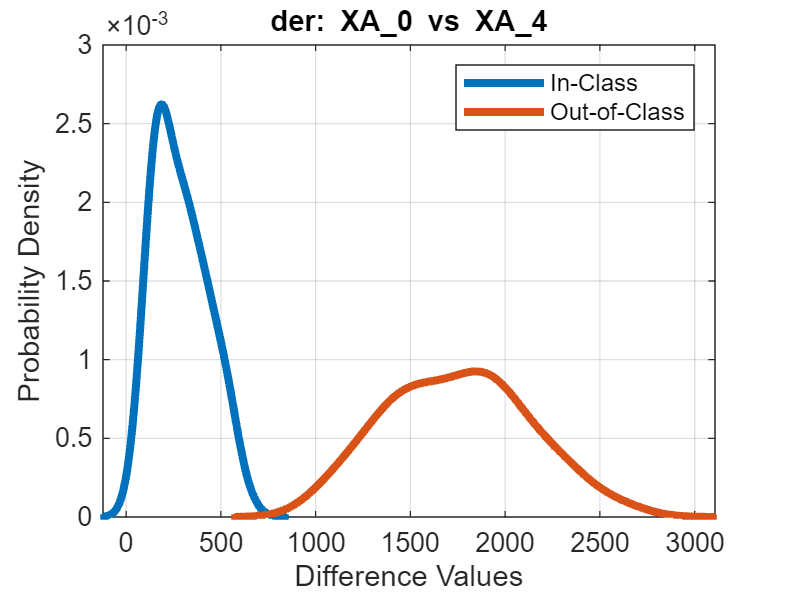

Class 1: iTAML\cifar10\iTAML_ses_0_XA_dcts.mat


Class 2: iTAML\cifar10\iTAML_ses_0_XB_dcts.mat



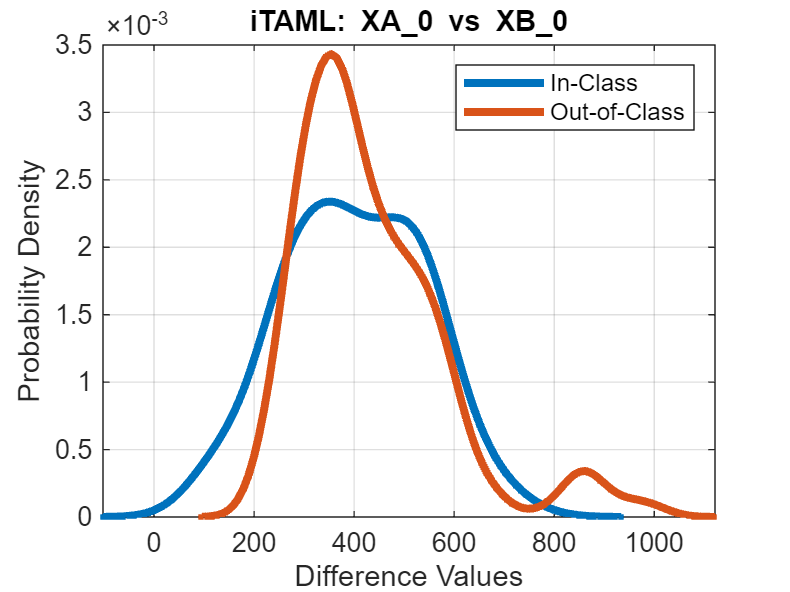

Class 1: RPSnet\cifar10\RPSnet_ses_0_XA_dcts.mat


Class 2: RPSnet\cifar10\RPSnet_ses_0_XB_dcts.mat



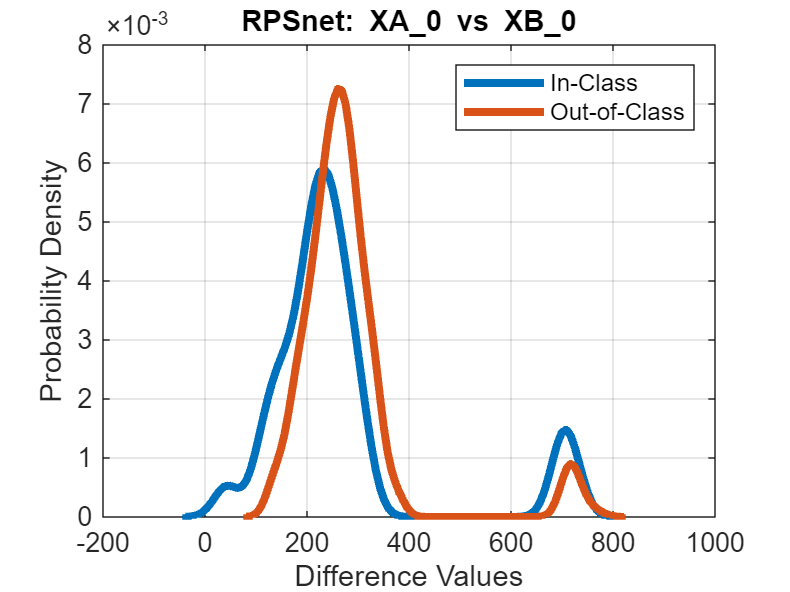

Class 1: foster\cifar10\foster_ses_0_XA_dcts.mat


Class 2: foster\cifar10\foster_ses_0_XB_dcts.mat



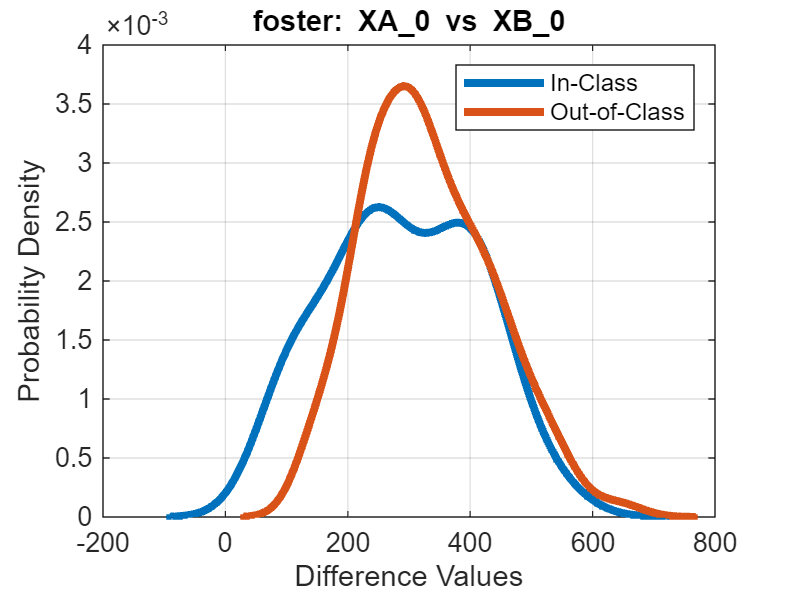

Class 1: memo\cifar10\memo_ses_0_XA_dcts.mat


Class 2: memo\cifar10\memo_ses_0_XB_dcts.mat



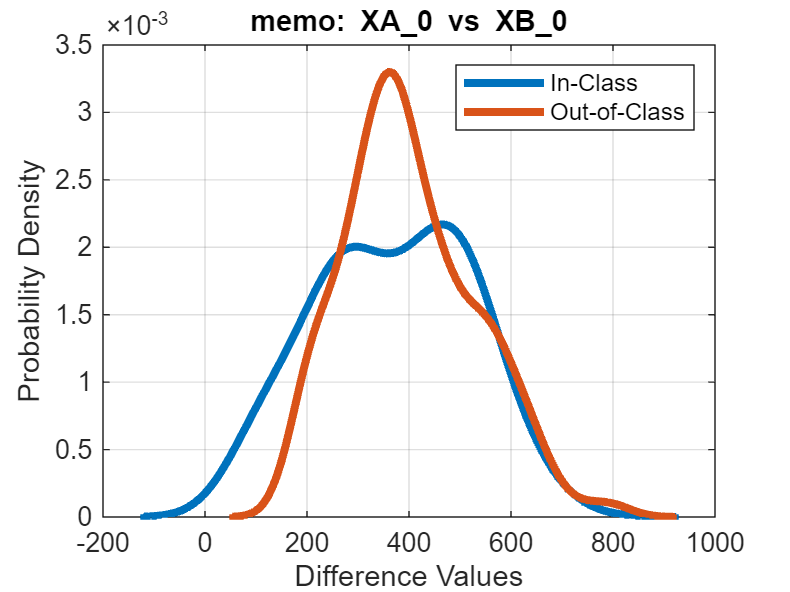

Class 1: der\cifar10\der_ses_0_XA_dcts.mat


Class 2: der\cifar10\der_ses_0_XB_dcts.mat



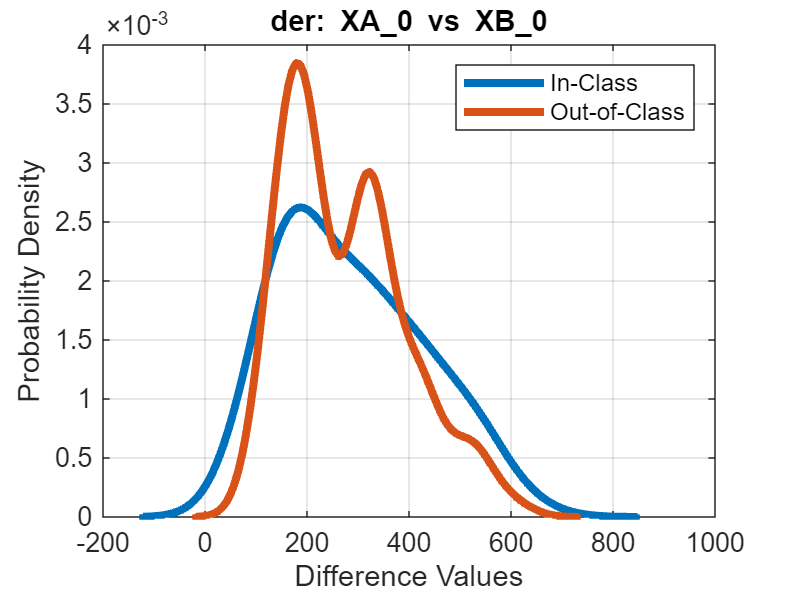

% Generate All PDFs

dataset = 'cifar10';

algs = {'iTAML', 'RPSnet', 'DGR', 'foster', 'memo', 'der'};
%algs = {'iTAML', 'RPSnet'};
if dataset ~= "mnist"
    algs(algs=="DGR") = [];
end

paths = {{'ses_0_XA_dcts.mat','ses_4_XA_dcts.mat'},
         {'ses_0_XA_dcts.mat','ses_0_XB_dcts.mat'}};

%paths = {{'ses_0_XA_dcts.mat','ses_9_XA_dcts.mat'},
%         {'ses_0_XA_dcts.mat','ses_0_XB_dcts.mat'}};

titles = ["XA\_0 vs XA\_4", "XA\_0 vs XB\_0", "XA\_4 vs XB\_4"];


for i=1:length(paths)
    for j=1:length(algs)

        
        class1 = load(sprintf("%s\\%s\\%s_%s", algs{j}, dataset, algs{j}, paths{i}{1}));
        fprintf('Class 1: %s\n', sprintf("%s\\%s\\%s_%s", algs{j}, dataset, algs{j}, paths{i}{1}))
        fns = fieldnames(class1);
        data1 = class1.(fns{1});
        p1=gkdeb(data1);
        
        class2 = load(sprintf("%s\\%s\\%s_%s", algs{j}, dataset, algs{j}, paths{i}{2}));
        fprintf('Class 2: %s\n\n', sprintf("%s\\%s\\%s_%s", algs{j}, dataset, algs{j}, paths{i}{2}))
        fns = fieldnames(class2);
        data2 = class2.(fns{1});
        p2=gkdeb(data2);
    
        % Plot both PDFs
        fig = figure;
        
        % Plot the PDF
        plot(p1.x, p1.pdf, '.-', 'LineWidth', 3);
        title(sprintf("%s: %s", algs{j}, titles(i)));
        xlabel('Difference Values');
        ylabel('Probability Density');
        hold on;
        
        % Plot the PDF
        plot(p2.x, p2.pdf, '.-', 'LineWidth', 3);
        hold off;
        
        legend('In-Class', 'Out-of-Class');
        grid on;
    
        %copygraphics(fig); % Copy the figure to the clipboard
        % Wait until the figure is closed
        %uiwait(fig);
    end
end